yy = rad2deg(cumtrapz(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.euler_cmd_y));

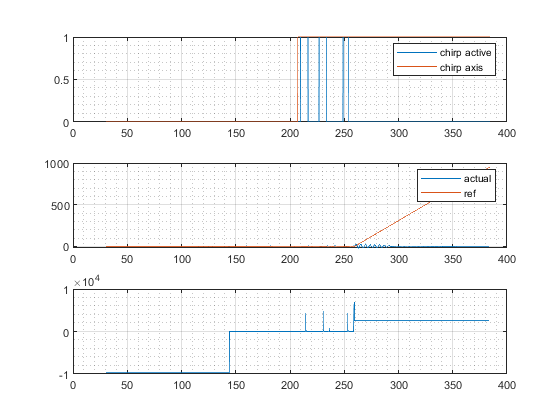

figure(1)
clf
ax1 = subplot(3,1,1);
plot(t,ac_data.EFF_FULL_INDI.chirp_active)
hold on
plot(t,ac_data.EFF_FULL_INDI.chirp_axis)
grid on
grid minor
legend("chirp active","chirp axis")

ax2 = subplot(3,1,2);
plot(t,ac_data.EFF_FULL_INDI.theta_alt)
hold on
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,yy)
grid on
grid minor
legend("actual","ref")

ax3 = subplot(3,1,3);
plot(t,ac_data.EFF_FULL_INDI.actuator_thrust_bx_pprz)
grid on
grid minor
linkaxes([ax1,ax2,ax3],'x');
hold off

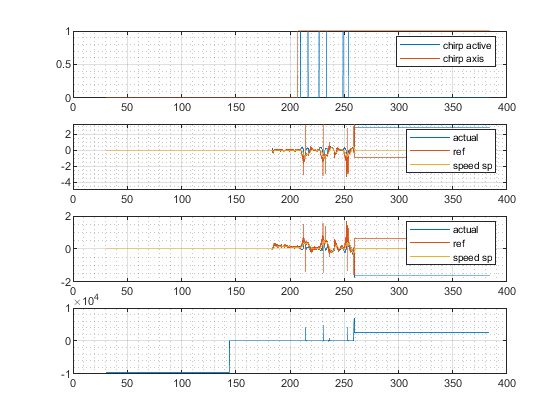

figure(2)
clf
ax1 = subplot(4,1,1);
plot(t,ac_data.EFF_FULL_INDI.chirp_active)
hold on
plot(t,ac_data.EFF_FULL_INDI.chirp_axis)
grid on
grid minor
legend("chirp active","chirp axis")

ax2 = subplot(4,1,2);
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.accelned_filt_x)
hold on
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.sp_accel_x)
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.speed_sp_x)
%plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,cumtrapz(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.sp_accel_x))
grid on
grid minor
legend("actual","ref","speed sp")

ax3 = subplot(4,1,3);
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.accelned_filt_y)
hold on
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.sp_accel_y)
plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.speed_sp_y)
%plot(ac_data.GUIDANCE_INDI_HYBRID.timestamp,cumtrapz(ac_data.GUIDANCE_INDI_HYBRID.timestamp,ac_data.GUIDANCE_INDI_HYBRID.sp_accel_y))
grid on
grid minor
legend("actual","ref","speed sp")

ax4 = subplot(4,1,4);
plot(t,ac_data.EFF_FULL_INDI.actuator_thrust_bx_pprz)
grid on
grid minor
linkaxes([ax1,ax2,ax3,ax4],'x');
hold off